# Primer on Flux Balance Analysis and its applications

## Author(s); Jeff Orth, Ines Thiele, Ronan Fleming

## Reviewer(s); 

## INTRODUCTION

In this tutorial, several basic examples of how FBA can be used to analyze constraint-based models, as described in [0], are presented. Many more COBRA methods, including some that are covered in this tutorial, are also presented in the COBRA Toolbox v3.0 paper [ref].  A map of the core model is shown in Figure 1.  Formal reaction name abbreviations are listed in blue text, formal metabolite name abbreviations are listed in purple text. 

## Beginner COBRA methods

Example 0: Calculating growth rates 

Example 1.  Growth on alternate substrates

Example 2.  Production of cofactors and biomass precursors

Example 3.  Alternate optimal solutions

Example 4.  Robustness analysis

Example 5.  Phenotypic phase planes

Example 6.  Simulating gene knockouts

Example 7.  Which genes are essential for which biomass precursor? 

Example 8.  Which non-essential gene knockouts have the greatest effect on the network flexibility?

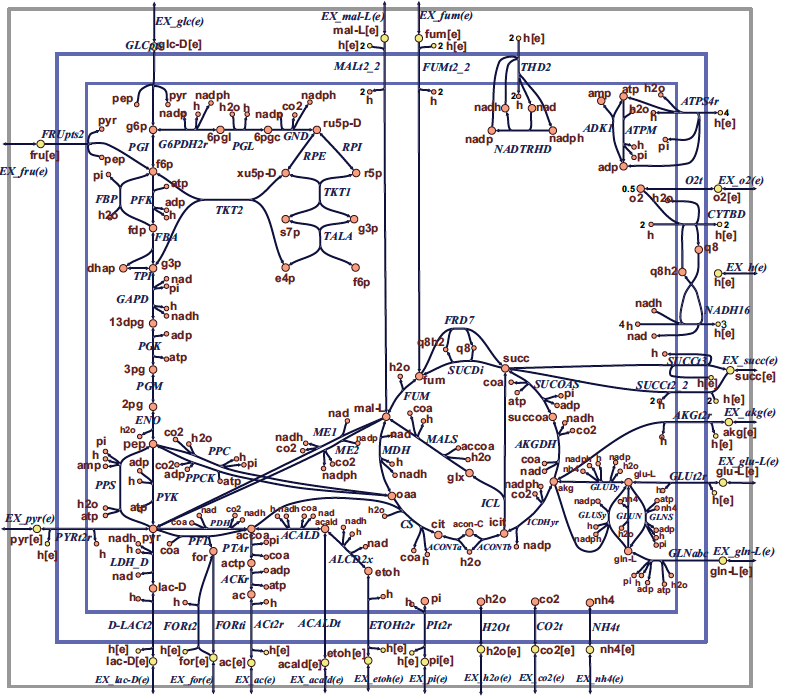

**Figure 1**  Map of the core E. coli metabolic network.  Orange circles represent cytosolic metabolites, yellow circles represent extracellular metabolites, and the blue arrows represent reactions.  Reaction name abbreviations are uppercase and metabolite name abbreviations are lowercase.  These flux maps were drawn using SimPheny and edited for clarity with Adobe Illustrator.

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most direct way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

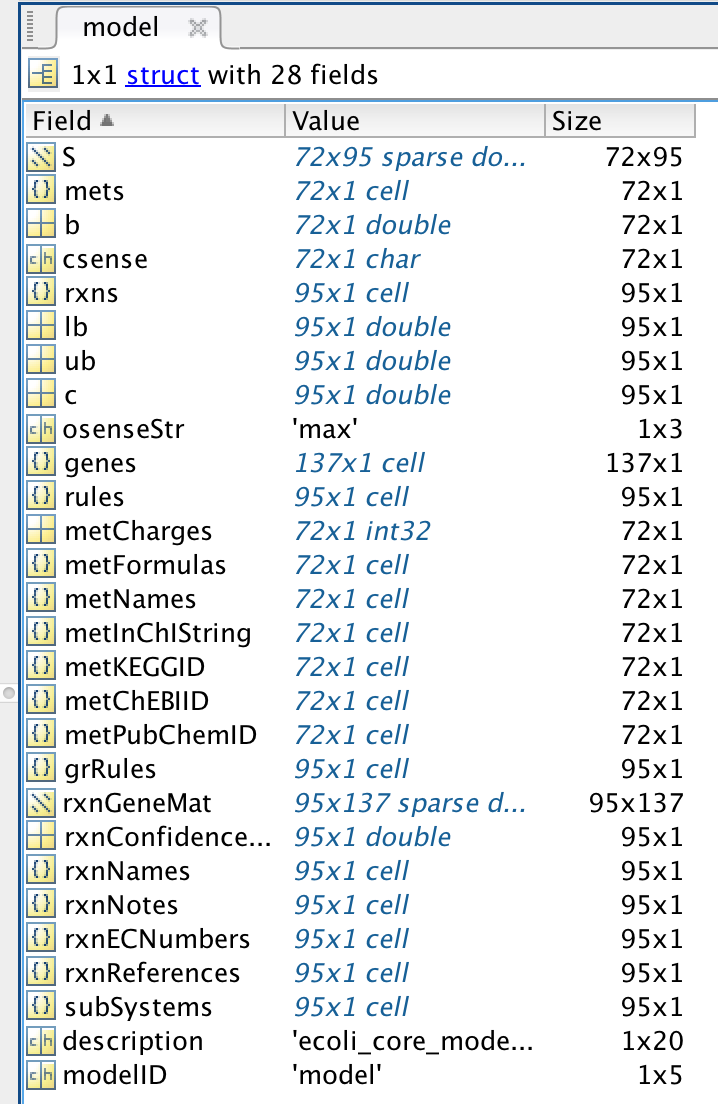

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

printConstraints(model,-1000,1000)

MinConstraints:
ATPM	8.39
EX_glc(e)	-10
maxConstraints:


## Calculating growth rates

Growth of E. coli on glucose can be simulated under aerobic conditions.  

#### What is the growth rate of *E. coli *on glucose (uptake rate = 18.5 mmol/gDW/h) under aerobic and anaerobic conditions?  

#### Hint: `changeRxnBounds`, `changeObjective`, `optimizeCbModel`, `printFluxVector`

To set the maximum glucose uptake rate to 18.5 mmol gDW-1 hr-1 (millimoles per gram dry cell weight per hour, the default flux units used in the COBRA Toolbox), enter:

model = changeRxnBounds(model,'EX_glc(e)',-18.5,'l');

This changes the lower bound ('l') of the glucose exchange reaction to -18.5, a biologically realistic uptake rate.  By convention, exchange reactions are written as export reactions (e.g. ‘glc[e] <==>’), so import of a metabolite is a negative flux.  

To allow unlimited oxygen uptake, enter:

model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');

By setting the lower bound of the oxygen uptake reaction to such a large number, it is practically unbounded.  Next, to ensure that the biomass reaction is set as the objective function, enter:

model = changeObjective(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2');

To perform FBA with maximization of the biomass reaction as the objective, enter:

FBAsolution = optimizeCbModel(model,'max')

FBAsolution = struct with fields:
         full: [95×1 double]
          obj: 1.6065
        rcost: [95×1 double]
         dual: [72×1 double]
        slack: [72×1 double]
       solver: 'pdco'
    algorithm: 'default'
         stat: 1
     origStat: 0
         time: 0.0119
        basis: []
            f: 1.6065
            x: [95×1 double]
            v: [95×1 double]
            w: [95×1 double]
            y: [72×1 double]
            s: [72×1 double]


FBAsolution.f  then give the value of the objective function, which should be 1.6531 mmol gDW-1 hr-1 

FBAsolution.f

ans = 1.6065

This is the same as 

model.c'*FBAsolution.v

ans = 1.6065

This means that the model predicts a growth rate of 1.6531 hr-1.  Inspection of the flux distribution vector FBAsolution.v shows that there is high flux in the glycolysis, pentose phosphate, TCA cycle, and oxidative phosphorylation pathways, and that no organic by-products are secreted (Figure 2a).

FBAsolution.v

ans =    -0.1013
   -0.0547
   -0.0884
   10.4868
   10.4868
   -0.0884
    0.2152
    5.2801
   -0.0316
   -0.0466


Inspection of the flux distribution is more convenient with the printFluxVector function

fluxData = FBAsolution.v;
nonZeroFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag)

ACALD               	     -0.1013
ACALDt              	    -0.05467
ACKr                	    -0.08843
ACONTa              	       10.49
ACONTb              	       10.49
ACt2r               	    -0.08843
ADK1                	      0.2152
AKGDH               	        5.28
AKGt2r              	    -0.03165
ALCD2x              	    -0.04665
ATPM                	       8.673
ATPS4r              	       79.98
Biomass_Ecoli_core_N(w/GAM)-Nmet2	       1.607
CO2t                	      -40.89
CS                  	       10.49
CYTBD               	       78.59
D-LACt2             	    -0.04574
ENO                 	       26.88
ETOHt2r             	    -0.04665
EX_ac(e)            	     0.08843
EX_acald(e)         	     0.05467
EX_akg(e)           	     0.03165
EX_co2(e)           	       40.89
EX_etoh(e)          	     0.04665
EX_for(e)           	      0.5022
EX_fru(e)           	   2.128e-05
EX_fum(e)           	   2.036e-05
EX_glc(e)           	      -18.48
EX_gln-L(e)         	   2.084e-05
E

## Display an optimal flux vector on a metabolic map

#### Which reactions/pathways are in use (look at the flux vector and flux map)?

#### Hint: `drawFlux`

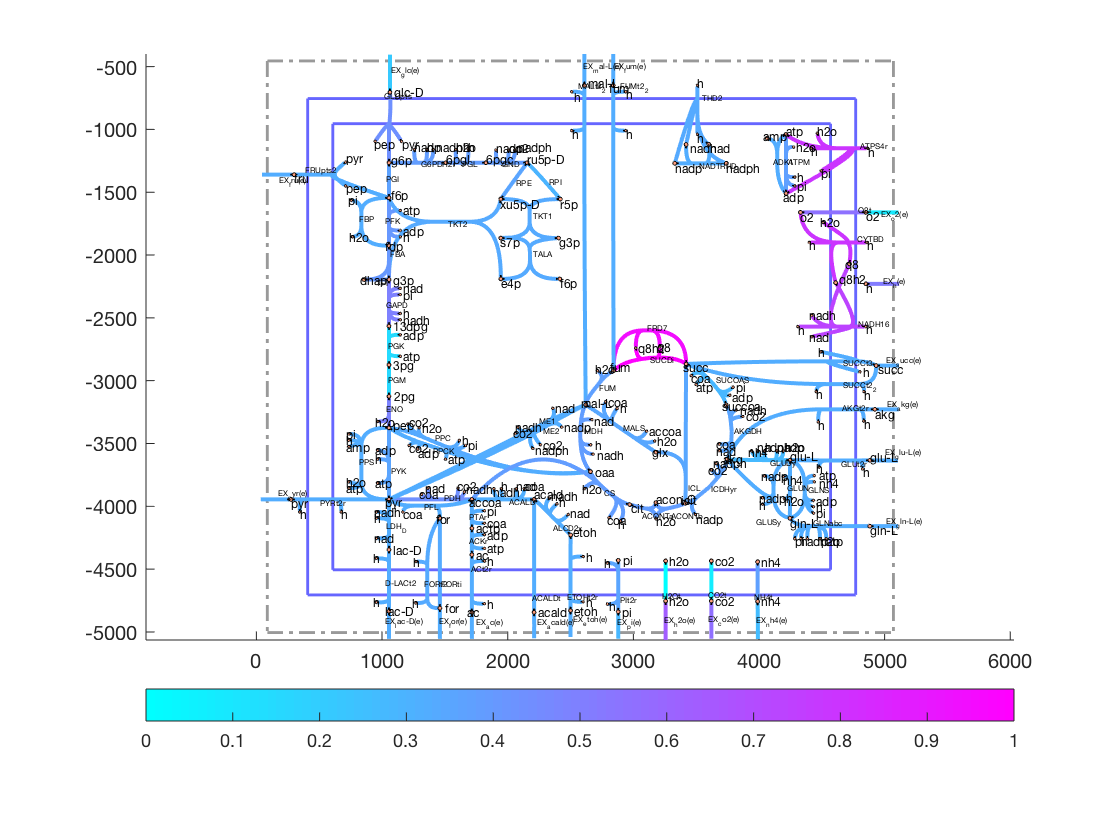

outputFormatOK = changeCbMapOutput('matlab');
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.v, options);

Next, the same simulation is performed under anaerobic conditions.  With the same model:

model = changeRxnBounds(model,'EX_o2(e)',0,'l');

The lower bound of the oxygen exchange reaction is now 0, so oxygen may not enter the system.  When optimizeCbModel is used as before, the resulting growth rate is now much lower, 0.4706 hr-1.  

FBAsolution2 = optimizeCbModel(model,'max');
FBAsolution2.f

ans = 0.4148

#### What reactions of oxidative phosphorylation are active in anaerobic conditions?

#### Hint: `printFluxVector` `drawFlux`

The flux distribution shows that oxidative phosphorylation is not used in these conditions, and that acetate, formate, and ethanol are produced by fermentation pathways (Figure 2b). Inspection of both flux vectors for comparison:

fluxData = [FBAsolution.v,FBAsolution2.v];
nonZeroFlag = 1;
excFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag, excFlag)

Biomass_Ecoli_core_N(w/GAM)-Nmet2	       1.607      0.4148
EX_ac(e)            	     0.08843       11.16
EX_acald(e)         	     0.05467      0.3076
EX_akg(e)           	     0.03165     0.07803
EX_co2(e)           	       40.89       2.057
EX_etoh(e)          	     0.04665       16.53
EX_for(e)           	      0.5022       29.05
EX_fru(e)           	   2.128e-05   2.195e-05
EX_fum(e)           	   2.036e-05   1.963e-05
EX_glc(e)           	      -18.48      -18.43
EX_gln-L(e)         	   2.084e-05   2.077e-05
EX_glu-L(e)         	     0.02723     0.06891
EX_h2o(e)           	       52.75      -10.22
EX_h(e)             	       33.11       50.97
EX_lac-D(e)         	     0.04574      0.5303
EX_mal-L(e)         	    2.03e-05   1.984e-05
EX_nh4(e)           	      -8.787      -2.331
EX_o2(e)            	       -39.3   3.626e-05
EX_pi(e)            	       -5.91      -1.526
EX_pyr(e)           	     0.05553      0.2642
EX_succ(e)          	     0.03619      0.6749


%drawFlux(map, model, FBAsolution2.v, options);

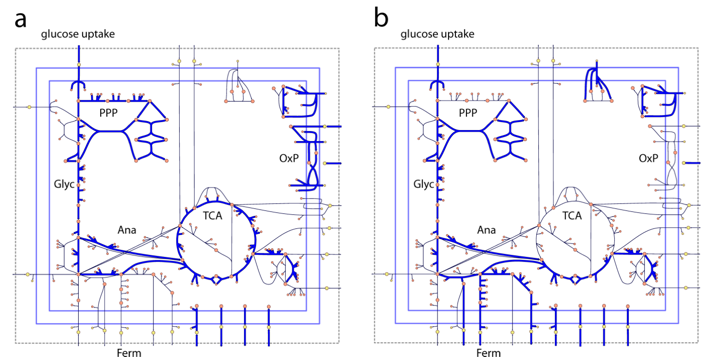

**Figure 2 ** flux vectors computed by FBA can be visualized on network maps.  In these two examples, the thick blue arrows represent reactions carrying flux, and the thin black arrows represent unused reactions.  These maps show the state of the E. coli core model with maximum growth rate as the objective (Z) under aerobic (a) and anaerobic (b) conditions.  Reactions that are in use have thick blue arrows, while reactions that carry 0 flux have thin black arrows. The metabolic pathways shown in these maps are glycolysis (Glyc), pentose phosphate pathway (PPP), TCA cycle (TCA), oxidative phosphorylation (OxP), anaplerotic reactions (Ana), and fermentation pathways (Ferm). 

## Example 1.  Growth on alternate substrates

Just as FBA was used to calculate growth rates of E. coli on glucose, it can also be used to simulate growth on other substrates.  The core E. coli model contains exchange reactions for 13 different organic compounds, each of which can be used as the sole carbon source under aerobic conditions. 

#### What is the growth rate of *E. coli *on succinate?

#### Hint: `changeRxnBounds`

Before trying out new boundary conditions on a model, make sure one's starting point is appropriate.

model = modelOri;

For example, to simulate growth on succinate instead of glucose, first use the changeRxnBounds function to set the lower bound of the glucose exchange reaction (EX_glc(e)) to 0.  

model = changeRxnBounds(model,'EX_glc(e)',0,'l');

Then use changeRxnBounds to set the lower bound of the succinate exchange reaction (EX_succ(e)) to -20 mmol gDW-1 hr-1 (an arbitrary uptake rate).  

model = changeRxnBounds(model,'EX_succ(e)',-20,'l');

As in the glucose examples, make sure that the biomass reaction is set as the objective (the function checkObjective can be used to identify the objective reaction(s)), 

checkObjective(model);

summaryT = 23×5 table
    Coefficient    Metabolite    metID                Reaction                 RxnID
    ___________    __________    _____    _________________________________    _____

       -1.496       3pg[c]         3      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
      -3.7478       accoa[c]      10      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
        59.81       adp[c]        13      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       4.1182       akg[c]        14      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       -59.81       atp[c]        17      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       3.7478       coa[c]        21      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
       -0.361       e4p[c]        23      Biomass_Ecoli_core_N(w/GAM)-Nmet2     13  
      -0.0709       f6p[c]        26      

Use optimizeCbModel to perform FBA, then the growth rate, given by FBAsolution.f, will be 0.8401 hr-1. 

FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = 0.8087

changeCobraSolver('pdco','QP')


 > pdco interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2019b.


ans = logical
   1


FBAsolution = optimizeCbModel(model,'max',1e-6);

Growth can also be simulated under anaerobic conditions with any substrate by using changeRxnBounds to set the lower bound of the oxygen exchange reaction (EX_o2(e)) to 0 mmol gDW-1 hr-1, so no oxygen can enter the system.  When this constraint is applied and succinate is the only organic substrate, optimizeCbModel returns a growth rate of 0 hr-1

model = changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = 1.0633e-10

In this case, FBA predicts that growth is not possible on succinate under anaerobic conditions.  Because the maximum amount of ATP that can be produced from this amount of succinate is less than the minimum bound of 8.39 mmol gDW-1 hr 1 of the ATP maintenance reaction, ATPM, there is no feasible solution.

## Batch prediction of growth rates on different substrates

#### What is the growth rate of E. coli on all 13 substrates in the core model, aerobically and anaerobically?

#### Hint: Use a `for` loop, with `changeRxnBounds` and `optimizeCbModel`

FBA predicted growth rates for all 13 organic substrates in the E. coli core model under both aerobic and anaerobic conditions are calulated with:

% calculate growth rates on alternate carbon sources
GrowthRates{1,1}='CarbonSource';
GrowthRates{1,2}='Aerobic';
GrowthRates{1,3}='Anaerobic';
CS={
    'EX_ac(e)'
    'EX_acald(e)'
    'EX_akg(e)'
    'EX_etoh(e)'
    'EX_fru(e)'
    'EX_fum(e)'
    'EX_glc(e)'
    'EX_gln-L(e)'
    'EX_glu-L(e)'
    'EX_lac-D(e)'
    'EX_mal-L(e)'
    'EX_pyr(e)'
    'EX_succ(e)'
    };
% loop through the carbon sources
for i=1:length(CS)
    GrowthRates{i+1,1}=CS{i};
    model = modelOri;
    model = changeRxnBounds(model,'EX_glc(e)',0,'l');
    model = changeRxnBounds(model,CS{i},-20,'l');
    % first aerobic
    model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
    FBAsolution = optimizeCbModel(model,'max');
    GrowthRates{i+1,2}=FBAsolution.f;
    % then anaerobic
    model = changeRxnBounds(model,'EX_o2(e)',0,'l');
    FBAsolution = optimizeCbModel(model,'max');
    GrowthRates{i+1,3}=FBAsolution.f;
end

The maximum growth rate of the core E. coli model on one of its 13 different organic substrates, computed by FBA:

GrowthRates

GrowthRates = 14×3 cell array
    {'CarbonSource'}    {'Aerobic'}    {'Anaerobic' }
    {'EX_ac(e)'    }    {[ 0.3551]}    {[1.7932e-10]}
    {'EX_acald(e)' }    {[ 0.5523]}    {[1.2238e-05]}
    {'EX_akg(e)'   }    {[ 1.0521]}    {[2.0899e-10]}
    {'EX_etoh(e)'  }    {[ 0.6698]}    {[1.3712e-10]}
    {'EX_fru(e)'   }    {[ 1.7486]}    {[    0.4405]}
    {'EX_fum(e)'   }    {[ 0.7546]}    {[1.6362e-09]}
    {'EX_glc(e)'   }    {[ 1.7480]}    {[    0.4403]}
    {'EX_gln-L(e)' }    {[ 1.0991]}    {[9.5845e-11]}
    {'EX_glu-L(e)' }    {[ 1.1796]}    {[2.0112e-10]}
    {'EX_lac-D(e)' }    {[ 0.6725]}    {[1.4558e-09]}
    {'EX_mal-L(e)' }    {[ 0.7546]}    {[1.6371e-09]}
    {'EX_pyr(e)'   }    {[ 0.5537]}    {[    0.0040]}
    {'EX_succ(e)'  }    {[ 0.8087]}    {[1.0633e-10]}


Growth rate was calculated for both aerobic and anaerobic conditions for each substrate, and the maximum substrate uptake rate was set to 20 mmol gDW-1 hr-1 for every substrate. The growth rates are all much lower anaerobically (0 hr-1 in most cases) because the electron transport chain cannot be used to fully oxidize the substrates and generate as much ATP.

### Example 2.  Production of cofactors and biomass precursors

FBA can also be used to determine the maximum yields of important cofactors and biosynthetic precursors from glucose and other substrates [12].  

#### What is the maximum yield of ATP per mol glucose?

#### Hint: use changeObjective to set the model to maximise the ATP hydrolysis reaction.

In this example, the maximum yields of the cofactors ATP, NADH, and NADPH from glucose under aerobic conditions are calculated. To calculate optimal ATP production, first use changeRxnBounds to constrain the glucose exchange reaction (EX_glc(e)) to exactly -1 mmol gDW-1 hr-1 by setting both the lower and upper bounds to -1 ('b'). 

model = modelOri;
printConstraints(model,-1000,1000)

MinConstraints:
ATPM	8.39
EX_glc(e)	-10
maxConstraints:


model = changeRxnBounds(model,'EX_glc(e)',-1,'b');

Next, set the ATP maintenance reaction (ATPM) as the objective to be maximized using changeObjective.  

model = changeObjective(model,'ATPM');

ATPM is a stoichiometrically balanced reaction that hydrolyzes ATP (atp[c]) and produces ADP (adp[c]), inorganic phosphate (pi[c]), and a proton (h[c]).  It works as an objective for maximizing ATP production because in order to consume the maximum amount of ATP, the network must first produce ATP by the most efficient pathways available by recharging the produced ADP.  The constraint on this reaction should be removed by using changeRxnBounds to set the lower bounds to 0.  By default, this reaction has a lower (and upper) bound of 8.39 mmol gDW-1 hr-1 to simulate non-growth associated maintenance costs.  

model = changeRxnBounds(model,'ATPM',0,'l');

Use optimizeCbModel to calculate the maximum yield of ATP, which is 17.5 mol ATP/mol glucose.

FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = 17.4735

 Inspection of the flux vectors:

fluxData = FBAsolution.v;
nonZeroFlag = 1;
excFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag, excFlag)

ATPM                	       17.47
EX_ac(e)            	   0.0002358
EX_acald(e)         	   0.0001541
EX_akg(e)           	   8.898e-05
EX_co2(e)           	       5.996
EX_etoh(e)          	   0.0001335
EX_for(e)           	    0.001446
EX_fru(e)           	   1.507e-05
EX_fum(e)           	   2.113e-05
EX_glc(e)           	          -1
EX_gln-L(e)         	   1.884e-05
EX_glu-L(e)         	   8.009e-05
EX_h2o(e)           	       5.996
EX_h(e)             	    0.002421
EX_lac-D(e)         	   0.0001293
EX_mal-L(e)         	   2.126e-05
EX_nh4(e)           	   -5.66e-05
EX_o2(e)            	      -5.997
EX_pi(e)            	    4.64e-05
EX_pyr(e)           	   0.0001541
EX_succ(e)          	   0.0001096


model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = changeObjective(model,'ATPM');
model = changeRxnBounds(model,'ATPM',0,'l');
FBAsolution = optimizeCbModel(model,'max');
FBAsolution.f

ans = 17.4735

#### What is the maximum yield of NADH and NADPH per mol glucose in aerobic and anaerobic conditions?

#### Hint: check the default constraints on the model before proceeding.

Calculation of the yields of NADH and NADPH one at a time can be performed in a similar manner.  First, constrain ATPM to 0 mmol gDW-1 hr-1 flux ('b') so the cell is not required to produce ATP, and also cannot consume any ATP using this reaction.  Add stoichiometrically balanced NADH and NADPH consuming reactions using the function addReaction, and set these as the objectives using changeObjective.  The maximum yields of ATP, NADH, and NADPH and biomass precursors are calculated with:  

% calculate the ATP, NADH, NADPH precursor yields
Yields{1,1}='Cofactor';
Yields{1,2}='Yield aerobic';
Yields{1,3}='Yield anaerobic';

% ATP
Yields{2,1}='ATP';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeObjective(model,'ATPM');
FBAsolution_maxATP = optimizeCbModel(model,'max');
Yields{2,2}=FBAsolution_maxATP.f;
model = changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolution_maxATPanaer = optimizeCbModel(model,'max');
Yields{2,3}=FBAsolution_maxATPanaer.f;

% NADH
Yields{3,1}='NADH';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addReaction(model,'NADH_drain','nadh[c] -> nad[c] + h[c]');

NADH_drain	nadh[c] 	->	h[c] + nad[c] 


model = changeObjective(model,'NADH_drain');
FBAsolution_maxNADH = optimizeCbModel(model,'max');
Yields{3,2}=FBAsolution_maxNADH.f;
model = changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolution_maxNADHanaer = optimizeCbModel(model,'max');
Yields{3,3}=FBAsolution_maxNADHanaer.f;

% NADPH
Yields{4,1}='NADPH';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addReaction(model,'NADPH_drain','nadph[c] -> nadp[c] + h[c]');

NADPH_drain	nadph[c] 	->	h[c] + nadp[c] 


model = changeObjective(model,'NADPH_drain');
FBAsolution_maxNADPH = optimizeCbModel(model,'max');
Yields{4,2}=FBAsolution_maxNADPH.f;
model = changeRxnBounds(model,'EX_o2(e)',0,'l');
FBAsolution_maxNADPHanaer = optimizeCbModel(model,'max');
Yields{4,3}=FBAsolution_maxNADPHanaer.f;
Yields

Yields = 4×3 cell array
    {'Cofactor'}    {'Yield aerobic'}    {'Yield anaerobic'}
    {'ATP'     }    {[      17.4735]}    {[         2.6830]}
    {'NADH'    }    {[       9.9701]}    {[         5.9494]}
    {'NADPH'   }    {[       8.6989]}    {[         3.9565]}


**Table 2a** (above) The maximum yields of the cofactors ATP, NADH, and NADPH from glucose under aerobic conditions.  

## Sensitivity of a FBA solution

The sensitivity of an FBA solution is indicated by either shadow prices or reduced costs.  A shadow price is a derivative of the objective function with respect to the exchange of a metabolite.  It indicates how much the addition of that metabolite will increase or decrease the objective.  A reduced cost is the derivatives of the objective function with respect to the lower and upper bounds on a reaction, indicating how much relaxation, or tightening, of each bound increases, or decreases, the optimal objective, respectively.  In the COBRA Toolbox, shadow prices and reduced costs are calculated by optimizeCbModel.  The vector of m shadow prices is FBAsolution.y and the vector of n reduced costs is FBAsolution.rcost.

#### In the E. coli core model, when maximising ATP production, what is the shadow price of cytosolic protons? 

#### Hint: `FBAsolution.y`

model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeObjective(model,'ATPM');
printConstraints(model,-1000,1000)

MinConstraints:
EX_glc(e)	-1
maxConstraints:



FBAsolution_maxATP = optimizeCbModel(model,'max');

Check the optimal value of the objective

FBAsolution_maxATP.f

ans = 17.5000

The shadow price of cytosolic protons (h[c]) is -0.25. 

ind=strcmp(model.mets,'h[c]');
FBAsolution_maxATP.y(ind)

ans = -0.2500

printFluxVector(model, FBAsolution_maxATP.v, 1)

ACONTa              	           2
ACONTb              	           2
AKGDH               	           2
ATPM                	        17.5
ATPS4r              	        13.5
CO2t                	          -6
CS                  	           2
CYTBD               	          12
ENO                 	           2
EX_co2(e)           	           6
EX_glc(e)           	          -1
EX_h2o(e)           	           6
EX_o2(e)            	          -6
FBA                 	           1
FUM                 	           2
GAPD                	           2
GLCpts              	           1
H2Ot                	          -6
ICDHyr              	           2
MDH                 	           2
NADH16              	          10
NADTRHD             	           2
O2t                 	           6
PDH                 	           2
PFK                 	           1
PGI                 	           1
PGK                 	          -2
PGM                 	          -2
PYK                 	           1
SUCDi         

Remove 4 units of cytoplasmic protons from the system and calculate the difference in the value of the optimal objective:

model.b(ind) = 4;
FBAsolution_maxATP_forceH = optimizeCbModel(model,'max');
FBAsolution_maxATP_forceH.f - FBAsolution_maxATP.f

ans = 1

#### What is your biochemical interpretation of this change in objective in the current context?

#### Hint: printFluxVector, drawFlux

This is a unique solution (see Example 3). 

dv = FBAsolution_maxATP_forceH.v-FBAsolution_maxATP.v;
dv(abs(dv)<1e-5)=0;
printFluxVector(model, dv, 1)

ATPM                	           1
ATPS4r              	           1
EX_h(e)             	          -4


The flux map for optimal ATP production is shown below.  

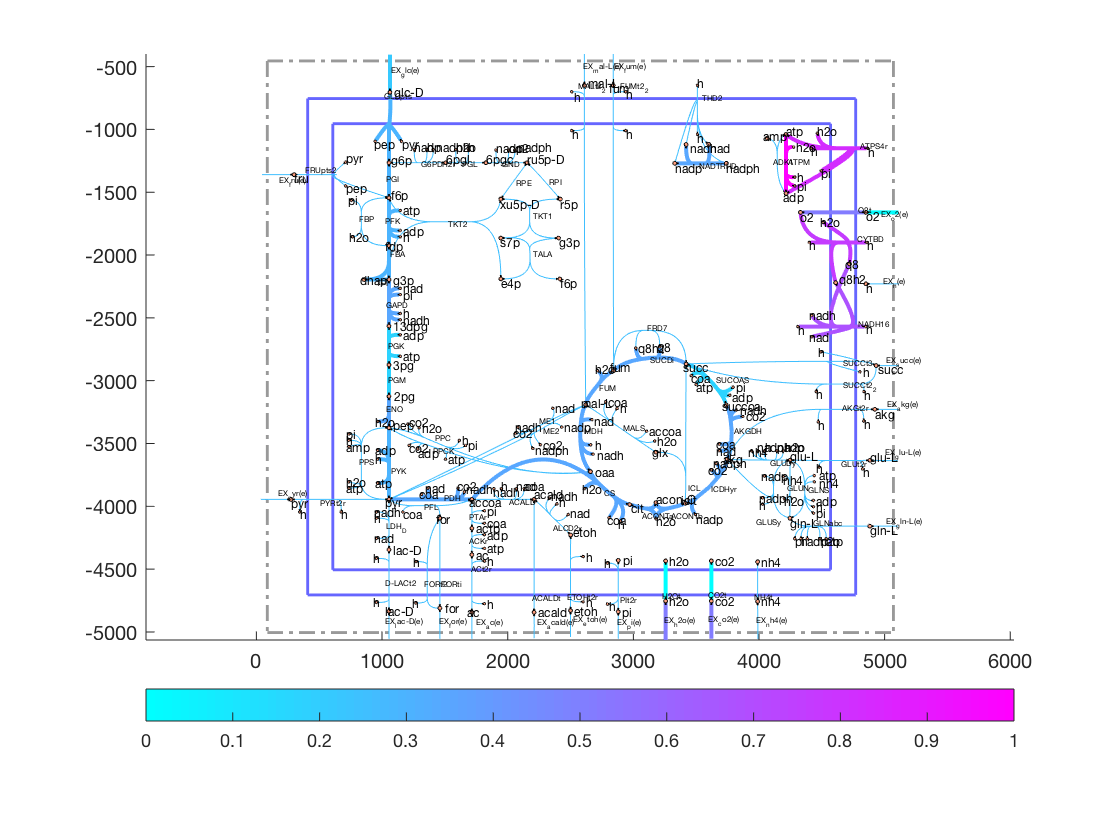

drawFlux(map, model, FBAsolution_maxATP.v, options);

ATP production is constrained by cytoplasmic proton balancing.  Cytoplasmic protons are produced by various metabolic reactions and also enter into the cell, from the extracellular compartment, via the ATP synthase reaction (ATPS4r).  At steady-state, an equal number of protons must be pumped out of the cytoplasm by the electron transport chain reactions or by excreting metabolites with symporters. Setting model.b(i) = 4, where i corresponds to cytoplasmic protons, h[c], removes 4 extra units of cytoplasmic protons from the system allowing 4 extra extracellular protons to enter the system that then enter the cell via the ATP synthase reaction, generating one extra unit of ATP. This increases the maximum rate of ATP synthesis by one unit, thereby increasing the ATP yield from glucose by 1 mol ATP/mol glucose. 

#### In the E. coli core model, when maximising ATP production, what is the reduced cost of glucose exchange? 

#### Hint: FBAsolution.rcost

rcost = FBAsolution_maxATP.rcost;
rcost(abs(rcost)<1e-4)=0;
flux=FBAsolution_maxATP.v;
printFluxVector(model, [model.lb,flux,model.ub,rcost], 1)

ACALD               	       -1000           0        1000           0
ACALDt              	       -1000           0        1000           0
ACKr                	       -1000   1.202e-32        1000           0
ACONTa              	       -1000           2        1000           0
ACONTb              	       -1000           2        1000           0
ACt2r               	       -1000          -0        1000           0
ADK1                	       -1000           0        1000           0
AKGDH               	           0           2        1000           0
AKGt2r              	       -1000          -0        1000           0
ALCD2x              	       -1000           0        1000           0
ATPM                	           0        17.5        1000           0
ATPS4r              	       -1000        13.5        1000           0
Biomass_Ecoli_core_N(w/GAM)-Nmet2	           0           0        1000       188.3
CO2t                	       -1000          -6        1000           0
CS     


ind=strcmp(model.rxns,'EX_glc(e)');
FBAsolution_maxATP.rcost(ind)

ans = 17.5000

model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-2,'l'); %note the change in the lower bound from -1 to -2
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeObjective(model,'ATPM');
FBAsolution_maxATP_moreGlc = optimizeCbModel(model,'max');

By changing the lower bound on glucose exhange from -1 to -2, we see that the value of the objective increases by 17.5, which is equal to the reduced cost of glucose obtained from FBAsolution_maxATP.rcost:

FBAsolution_maxATP_moreGlc.f - FBAsolution_maxATP.f

ans = 17.5000

Display the change in the flux vector:

dv = FBAsolution_maxATP_moreGlc.v-FBAsolution_maxATP.v;
dv(abs(dv)<1e-4)=0;
printFluxVector(model, dv, 1)

ACONTa              	           2
ACONTb              	           2
AKGDH               	           2
ATPM                	        17.5
ATPS4r              	        13.5
CO2t                	          -6
CS                  	           2
CYTBD               	          12
ENO                 	           2
EX_co2(e)           	           6
EX_glc(e)           	          -1
EX_h2o(e)           	           6
EX_o2(e)            	          -6
FBA                 	           1
FUM                 	           2
GAPD                	           2
GLCpts              	           1
H2Ot                	          -6
ICDHyr              	           2
MDH                 	           2
NADH16              	          10
NADTRHD             	           2
O2t                 	           6
PDH                 	           2
PFK                 	           1
PGI                 	           1
PGK                 	          -2
PGM                 	          -2
PYK                 	           1
SUCDi         

#### In the E. coli core model, what is the shadow price of cytosolic protons at (a) maximum NADH yield, and (b) at maximum NADPH yield? 

NADH and NADPH production are also ultimately limited by proton balancing.  For maximum NADH yield, the proton shadow price is -0.1362.  

FBAsolution_maxNADH.y(strcmp(model.mets,'h[c]'))

ans = -0.1362

For maximum NADPH yield, the proton shadow price is -0.1111.  

FBAsolution_maxNADPH.y(strcmp(model.mets,'h[c]'))

ans = -0.1111

#### What is your biochemical interpretation of these value in the current context?

#### Hint: `drawFlux`

The stoichiometry of the network also limits the production of NADH and NADPH.  Glucose has 12 electron pairs that can be donated to redox carriers such as NAD+ or NADP+, but when the TCA cycle is used, two of these electron pairs are used to reduce the quinone q8[c] in the succinate dehydrogenase reaction (SUCDi), and thus cannot be used to produce NADH or NADPH.  The only pathway that can reduce 12 redox carriers with one molecule of glucose is the pentose phosphate pathway, but this is infeasible because this pathway generates no ATP, which is needed to pump out the protons that are produced.

YieldsShadowPrices = Yields(1:4,1:2);

Unrecognized function or variable 'Yields'.

YieldsShadowPrices{1,3}='ATP Shadow Price';
YieldsShadowPrices{2,3}=FBAsolution_maxATP.y(strcmp(model.mets,'atp[c]'));
YieldsShadowPrices{3,3}=FBAsolution_maxNADH.y(strcmp(model.mets,'atp[c]'));
YieldsShadowPrices{4,3}=FBAsolution_maxNADPH.y(strcmp(model.mets,'atp[c]'));
YieldsShadowPrices{1,4}='Constraint';
YieldsShadowPrices{2,4}='H+ balancing';
YieldsShadowPrices{3,4}='Energy, Stoichiometry';
YieldsShadowPrices{4,4}='Energy, Stoichiometry';
YieldsShadowPrices

**Table 2b** (above) The maximum yields of the cofactors ATP, NADH, and NADPH from glucose under aerobic conditions.  ATP Shadow Price is the shadow price of the metabolite atp[c], and the negative of this value indicates how much the addition of ATP to the system will increase the yield of the cofactor.  Constraint indicates what is limiting constraints on the yields are.  Energy constraints are due to the limited availability of ATP, while stoichiometry constraints indicate that the structure of the network prevents maximum yield.

The production of these cofactors can also be computed under anaerobic conditions by setting the lower bound of the oxygen exchange reaction (EX_o2(e)) to 0 mmol gDW-1 hr-1.  The results of these calculations are shown in Table 3.

YieldsShadowPricesAnaer = Yields(1:4,[1,3]);
YieldsShadowPricesAnaer{1,3}='ATP Shadow Price';
YieldsShadowPricesAnaer{2,3}=FBAsolution_maxATPanaer.y(strcmp(model.mets,'atp[c]'));
YieldsShadowPricesAnaer{3,3}=FBAsolution_maxNADHanaer.y(strcmp(model.mets,'atp[c]'));
YieldsShadowPricesAnaer{4,3}=FBAsolution_maxNADPHanaer.y(strcmp(model.mets,'atp[c]'));
YieldsShadowPricesAnaer{1,4}='Constraint';
YieldsShadowPricesAnaer{2,4}='H+ balancing';
YieldsShadowPricesAnaer{3,4}='Energy, Stoichiometry';
YieldsShadowPricesAnaer{4,4}='Energy, Stoichiometry';
YieldsShadowPricesAnaer

## Biosynthetic precursor yields

The core E. coli model contains 12 basic biosynthetic precursor compounds that are used to build macromolecules such as nucleic acids and proteins.  The maximum yield of each of these precursor metabolites from glucose can be calculated by adding a demand reaction for each one (a reaction that consumes the compound without producing anything) and setting these as the objectives for FBA.  A yield of 2 moles of a 3-carbon compound from 1 mole of 6-carbin glucose is 100% carbon conversion.

#### What is the maximum yield of 12 basic biosynthetic precursor compounds that are used to build macromolecules such as nucleic acids and proteins? W**hat is the percentage of the carbon atoms in glucose that are converted to the precursor compound (Carbon Conversion) in each case? **

#### Hint: what are the non-zero stoichiometric coefficients in the biomass reaction? See also `model.metFormulas`

Maximum yields of each of the 12 precursors are listed in Table 4.  Note that the demand reactions for acetyl-CoA (accoa[c]) and succinyl-CoA (succoa[c]) produce coenzyme-A (coa[c]), since this carrier molecule is not produced from glucose in the core model.

% calculate the ATP and biomass precursor yields
YieldsPrecursor{1,1}='Precursor';
YieldsPrecursor{1,2}='Yield aerobic';
YieldsPrecursor{1,3}='Carbon Conversion';
YieldsPrecursor{1,4}='ATP Shadow Price';
YieldsPrecursor{1,5}='Constraint';

% 3-phosphoglycerate
YieldsPrecursor{2,1}='3-phosphoglycerate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'3pg[c]');

Adding the following reactions to the model:
DM_3pg[c]	3pg[c] 	->	


model = changeObjective(model,'DM_3pg[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{2,2}=FBAsolution.f;
YieldsPrecursor{2,3}=[];
YieldsPrecursor{2,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{2,5}='-';

% Erythrose-4-phosphate
YieldsPrecursor{3,1}='Erythrose-4-phosphate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'e4p[c]');

Adding the following reactions to the model:
DM_e4p[c]	e4p[c] 	->	


model = changeObjective(model,'DM_e4p[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{3,2}=FBAsolution.f;
YieldsPrecursor{3,3}=[];
YieldsPrecursor{3,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{3,5}='Energy';

% Fructose-6-phosphate
YieldsPrecursor{4,1}='Fructose-6-phosphate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'f6p[c]');

Adding the following reactions to the model:
DM_f6p[c]	f6p[c] 	->	


model = changeObjective(model,'DM_f6p[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{4,2}=FBAsolution.f;
YieldsPrecursor{4,3}=[];
YieldsPrecursor{4,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{4,5}='Energy';

% Glyceraldehyde-3-phosphate
YieldsPrecursor{5,1}='Glyceraldehyde-3-phosphate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'g3p[c]');

Adding the following reactions to the model:
DM_g3p[c]	g3p[c] 	->	


model = changeObjective(model,'DM_g3p[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{5,2}=FBAsolution.f;
YieldsPrecursor{5,3}=[];
YieldsPrecursor{5,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{5,5}='Energy';

% Glucose-6-phosphate
YieldsPrecursor{6,1}='Glucose-6-phosphate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'g6p[c]');

Adding the following reactions to the model:
DM_g6p[c]	g6p[c] 	->	


model = changeObjective(model,'DM_g6p[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{6,2}=FBAsolution.f;
YieldsPrecursor{6,3}=[];
YieldsPrecursor{6,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{6,5}='Energy';

% Ribose-5-phosphate
YieldsPrecursor{7,1}='Ribose-5-phosphate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'r5p[c]');

Adding the following reactions to the model:
DM_r5p[c]	r5p[c] 	->	


model = changeObjective(model,'DM_r5p[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{7,2}=FBAsolution.f;
YieldsPrecursor{7,3}=[];
YieldsPrecursor{7,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{7,5}='Energy';

% Phosphoenolpyruvate
YieldsPrecursor{8,1}='Phosphoenolpyruvate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'pep[c]');

Adding the following reactions to the model:
DM_pep[c]	pep[c] 	->	


model = changeObjective(model,'DM_pep[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{8,2}=FBAsolution.f;
YieldsPrecursor{8,3}=[];
YieldsPrecursor{8,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{8,5}='-';

% Pyruvate
YieldsPrecursor{9,1}='Pyruvate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'pyr[c]');

Adding the following reactions to the model:
DM_pyr[c]	pyr[c] 	->	


model = changeObjective(model,'DM_pyr[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{9,2}=FBAsolution.f;
YieldsPrecursor{9,3}=[];
YieldsPrecursor{9,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{9,5}='-';

% Oxaloacetate
YieldsPrecursor{10,1}='Oxaloacetate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'oaa[c]');

Adding the following reactions to the model:
DM_oaa[c]	oaa[c] 	->	


model = changeObjective(model,'DM_oaa[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{10,2}=FBAsolution.f;
YieldsPrecursor{10,3}=[];
YieldsPrecursor{10,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{10,5}='-';

% 2-oxoglutarate
YieldsPrecursor{11,1}='2-oxoglutarate';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = addDemandReaction(model,'akg[c]');

Adding the following reactions to the model:
DM_akg[c]	akg[c] 	->	


model = changeObjective(model,'DM_akg[c]');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{11,2}=FBAsolution.f;
YieldsPrecursor{11,3}=[];
YieldsPrecursor{11,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{11,5}='Stoichiometry';

% Acetyl-CoA
YieldsPrecursor{12,1}='Acetyl-CoA';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = addReaction(model,'ACCOA_drain','accoa[c] -> coa[c]');

ACCOA_drain	accoa[c] 	->	coa[c] 


model = changeObjective(model,'ACCOA_drain');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{12,2}=FBAsolution.f;
YieldsPrecursor{12,3}=[];
YieldsPrecursor{12,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{12,5}='Stoichiometry';

% Succinyl-CoA
YieldsPrecursor{13,1}='Succinyl-CoA';
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'b');
model = changeRxnBounds(model,'ATPM',0,'l');
model = addReaction(model,'SUCCOA_drain','succoa[c] -> coa[c]');

SUCCOA_drain	succoa[c] 	->	coa[c] 


model = changeObjective(model,'SUCCOA_drain');
FBAsolution = optimizeCbModel(model,'max');
YieldsPrecursor{13,2}=FBAsolution.f;
YieldsPrecursor{13,3}=[];
YieldsPrecursor{13,4}=FBAsolution.y(strcmp(model.mets,'atp[c]'));
YieldsPrecursor{13,5}='-';

YieldsPrecursor

YieldsPrecursor = 13×5 cell array
  Columns 1 through 3

    {'Precursor'        }    {'Yield aerobic'}    {'Carbon Conversion'}
    {'3-phosphoglycer…'}    {[       1.9643]}    {0×0 double         }
    {'Erythrose-4-pho…'}    {[       1.2738]}    {0×0 double         }
    {'Fructose-6-phos…'}    {[       0.8373]}    {0×0 double         }
    {'Glyceraldehyde-…'}    {[       1.6272]}    {0×0 double         }
    {'Glucose-6-phosp…'}    {[       0.8369]}    {0×0 double         }
    {'Ribose-5-phosph…'}    {[       0.9976]}    {0×0 double         }
    {'Phosphoenolpyru…'}    {[       1.9651]}    {0×0 double         }
    {'Pyruvate'         }    {[       1.9661]}    {0×0 double         }
    {'Oxaloacetate'     }    {[       1.9643]}    {0×0 double         }
    {'2-oxoglutarate'   }    {[       0.9812]}    {0×0 double         }
    {'Acetyl-CoA'       }    {[       1.9848]}    {0×0 double         }
    {'Succinyl-CoA'     }    {[       1.6055]}    {0×0 double         }

  Columns 4 t

**Table 4 ** The maximum yields of different biosynthetic precursors from glucose under aerobic conditions.  The precursors are 3pg (3-phospho-D-glycerate), pep (phosphoenolpyruvate), pyr (pyruvate), oaa (oxaloacetate), g6p (D-glucose-6-phosphate), f6p (D-fructose-6-phosphate), r5p (α-D-ribose-5-phosphate), e4p (D-erythrose-4-phosphate), g3p (glyceraldehyde-3-phosphate), accoa (acetyl-CoA), akg (2-oxoglutarate), and succoa (succinyl-CoA).   ATP Shadow Price is the shadow price of the metabolite atp[c].  Constraint indicates what the limiting constraints on the yields are, preventing a yield of at least 100%.  Some precursors have a yield of over 100% because carbon from CO2 can be fixed in some reactions.

## Example 3.  Alternate optimal solutions

The flux distribution calculated by FBA is often not unique.  In many cases, it is possible for a biological system to achieve the same objective value by using alternate pathways, so phenotypically different alternate optimal solutions are possible.   A method that uses FBA to identify alternate optimal solutions is Flux Variability Analysis (FVA)[13].  This is a method that identifies the maximum and minimum possible fluxes through a particular reaction with the objective value constrained to be close to or equal to its optimal value.  Performing FVA on a single reaction using the basic COBRA Toolbox functions is simple.  First, use functions changeRxnBounds, changeObjective, and optimizeCbModel to perform FBA as described in the previous examples.  Get the optimal objective value (FBAsolution.f), and then set both the lower and upper bounds of the objective reaction to exactly this value.  Next, set the reaction of interest as the objective, and use FBA to minimize and maximize this new objective in two separate steps.  This will give the minimum and maximum possible fluxes through this reaction while contributing to the optimal objective value.

#### What reactions vary their optimal flux in the set of alternate optimal solutions to maximum growth of E. coli on succinate? Are there any reactions that are not used in one optimal solution but used in another optimal solution? What are the computational and biochemical aspects to consider when interpreting these alternate optimal solutions?

#### Hint: `fluxVariability`

Consider the variability of the malic enzyme reaction (ME1) in E. coli growing on succinate.  The minimum possible flux through this reaction is 0 mmol gDW-1 hr-1 and the maximum is 6.49 mmol gDW-1 hr-1.  In one alternate optimal solution, the ME1 reaction is used, but in another, it is not used at all.  The full code to set the model to these conditions and perform FVA on this reaction is:

model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',0,'l');
model = changeRxnBounds(model,'EX_succ(e)',-20,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
FBAsolution = optimizeCbModel(model,'max');
model = changeRxnBounds(model,'Biomass_Ecoli_core_N(w/GAM)-Nmet2',FBAsolution.f,'b');
model_ME1 = changeObjective(model,'ME1');
FBAsolution_ME1_Min = optimizeCbModel(model_ME1,'min');
FBAsolution_ME1_Max = optimizeCbModel(model_ME1,'max');
FBAsolution_ME1_Min.f

ans = 0.0013

FBAsolution_ME1_Max.f

ans = 16.6408

The COBRA Toolbox includes a built in function for performing FVA called `fluxVariability`.  This function is useful because it performs FVA on every reaction in a model.  When FVA is performed on every reaction in the E. coli core model for growth on succinate, eight reactions are found to be variable (Table 5).  Inspection of the variable reactions shows that conversion of L-matate to pyruvate may occur through several different pathways, each leading to the same maximum growth rate.  Flux vectors using combinations of these pathways are also valid solutions. Two of these alternate solutions are shown in Figure 4.

FVAresults=cell(size(model.S,2)+1,1);
FVAresults{1,1}='Reaction';
FVAresults{1,2}='Minimum Flux';
FVAresults{1,3}='Maximum Flux';
FVAresults(2:end,1)=model.rxns;
[minFlux, maxFlux, ~, ~] = fluxVariability(model, 100, 'max', [], 0, 1, 'FBA');
for n=1:size(model.S,2)
    FVAresults{n+1,2}=minFlux(n);
    FVAresults{n+1,3}=maxFlux(n);
end
bool=abs(maxFlux-minFlux)>=1e-6;
bool=[true;bool];
FVAresults=FVAresults(bool,:)

FVAresults = 85×3 cell array
    {'Reaction'}    {'Minimum Flux'}    {'Maximum Flux'}
    {'ACALD'   }    {[     -0.8811]}    {[     -0.0028]}
    {'ACALDt'  }    {[     -0.8815]}    {[     -0.0014]}
    {'ACKr'    }    {[     -1.3587]}    {[     -0.0013]}
    {'ACONTa'  }    {[      5.9996]}    {[      8.5689]}
    {'ACONTb'  }    {[      5.9996]}    {[      8.5689]}
    {'ACt2r'   }    {[     -1.3587]}    {[     -0.0013]}
    {'ADK1'    }    {[      0.0011]}    {[      5.8265]}
    {'AKGDH'   }    {[      1.8799]}    {[      7.6935]}
    {'AKGt2r'  }    {[     -0.4687]}    {[     -0.0015]}
    {'ALCD2x'  }    {[     -0.7612]}    {[     -0.0014]}
    {'ATPM'    }    {[      8.3911]}    {[     14.2266]}
    {'ATPS4r'  }    {[     55.2285]}    {[     62.9699]}
    {'CO2t'    }    {[    -45.5731]}    {[    -41.7011]}
    {'CS'      }    {[      5.9996]}    {[      8.5689]}
    {'CYTBD'   }    {[     63.8271]}    {[     69.2880]}


**Table 5 ** Variable reactions for growth on succinate (uptake rate = 20 mmol gDW-1 hr-1) under aerobic conditions.  The minimum and maximum possible flux for every reaction was calculated at the maximum growth rate and only reactions with variable fluxes are shown here.  FRD7 (fumarate reductase) and SUCDi (succinate dehydrogenase) always have highly variable fluxes in this model because they form a cycle that can carry any flux.  Physiologically, these fluxes are not relevant.  The other variable reactions are MDH (malate dehydrogenase), ME1 (malic enzyme (NAD)), ME2 (malic enzyme (NADP)), NADTRHD (NAD transhydrogenase), PPCK (phosphoenolpyruvate carboxykinase), and PYK (pyruvate kinase).

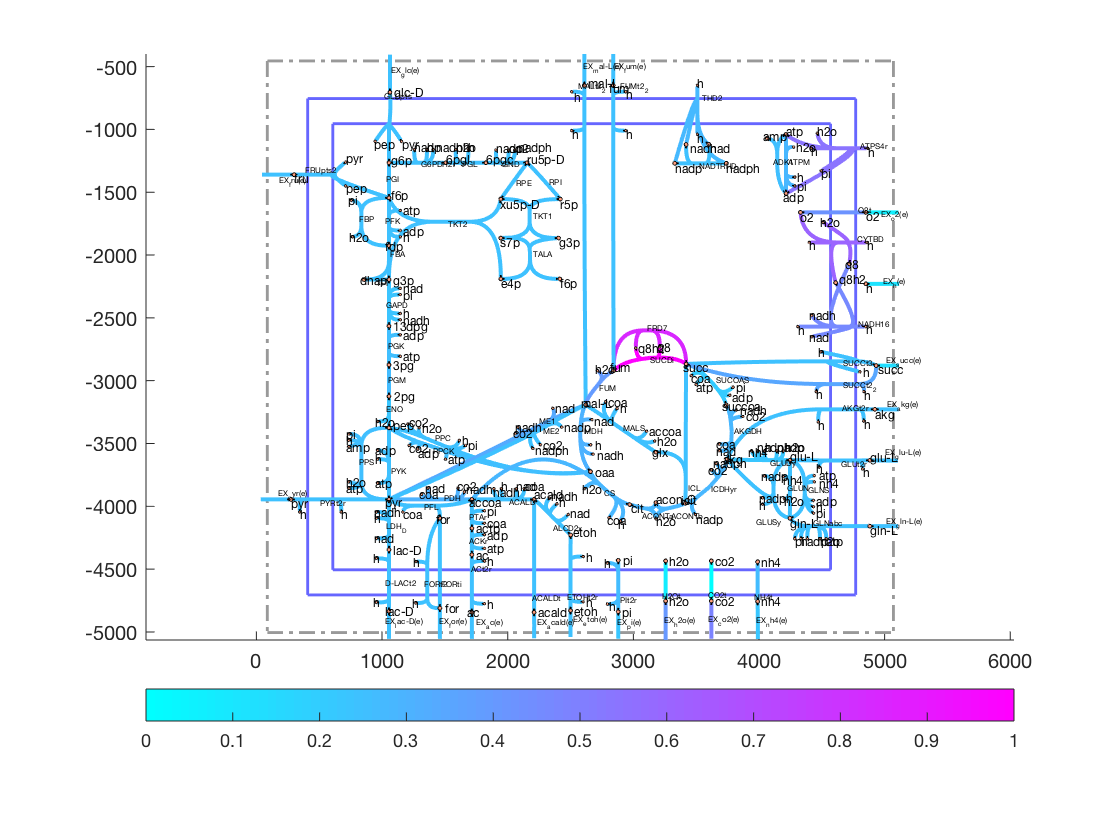

model_ME1 = changeObjective(model,'ME1');
FBAsolution_ME1_Max = optimizeCbModel(model_ME1,'max');
drawFlux(map, model, FBAsolution_ME1_Max.v, options);

**Figure 4a ** Flux maps for an alternate solutions for maximum aerobic growth on succinate.  The reaction ME1 is used to convert L-malate to pyruvate.

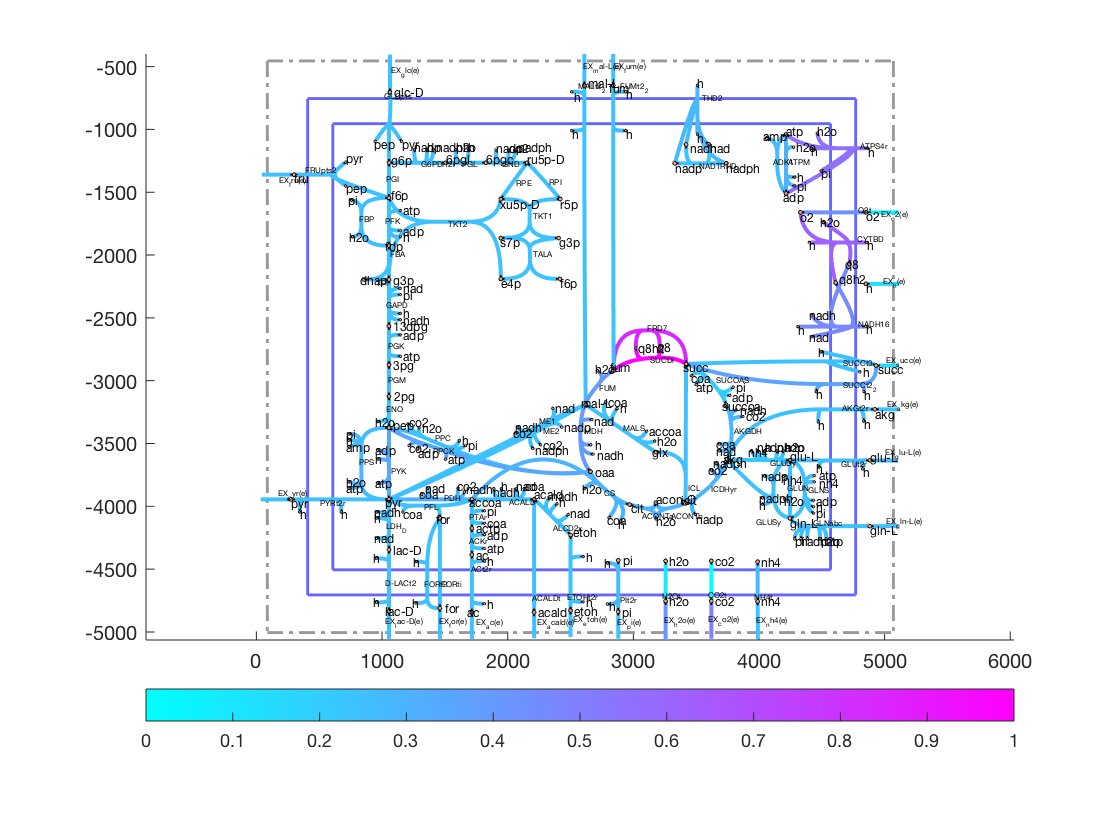

model_PYK = changeObjective(model,'PYK');
FBAsolution_PYK_Max = optimizeCbModel(model_PYK,'max');
drawFlux(map, model, FBAsolution_PYK_Max.v, options); 

**Figure 4b ** Flux maps for an alternate solutions for maximum aerobic growth on succinate.  ME1 is is not used at all, and the reaction PYK is used. ** The two alternative reactions are highlighted in red.**

## Example 4.  Robustness analysis

Another method that uses FBA to analyze network properties is robustness analysis [14].  In this method, the flux through one reaction is varied and the optimal objective value is calculated as a function of this flux.  This reveals how sensitive the objective is to a particular reaction.  There are many insightful combinations of reaction and objective that can be investigated with robustness analysis.  One example is examination of the effects of nutrient uptake on growth rate.  

#### What is the effect of varying glucose uptake rate on growth? At what uptake rates does glucose alone constrain growth?

#### Hint: fix the oxygen uptake rate to 17 mmol gDW-1 hr-1

To determine the effect of varying glucose uptake on growth, first use changeRxnBounds to set the oxygen uptake rate (EX_o2(e)) to 17 mmol gDW-1 hr-1, a realistic uptake rate.  Then, use a for loop to set both the upper and lower bounds of the glucose exchange reaction to values between 0 and -20 mmol gDW-1 hr-1, and use optimizeCbModel to perform FBA with each uptake rate.  Be sure to store each growth rate in a vector or other type of Matlab list.  The COBRA Toolbox also contains a function for performing robustness analysis (robustnessAnalysis) that can perform these functions. The full code to perform this robustness analysis is:

model = modelOri;
model = changeRxnBounds(model,'EX_o2(e)',-17,'b');
glucoseUptakeRates = zeros(21,1);
growthRates = zeros(21,1);
for i = 0:20
	model = changeRxnBounds(model,'EX_glc(e)',-i,'b');
        glucoseUptakeRates(i+1)=-i;
	FBAsolution = optimizeCbModel(model,'max');
	growthRates(i+1) = FBAsolution.f;
end

The results can then be plotted: 

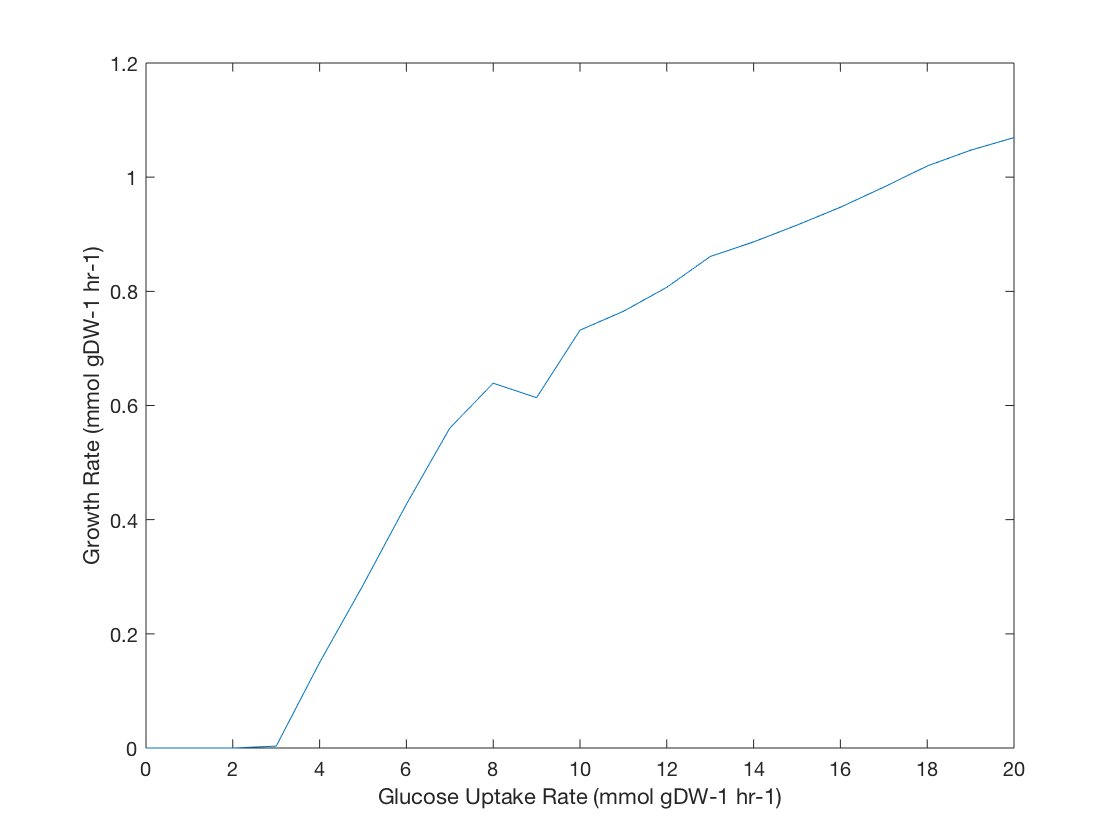

figure; 
plot(-glucoseUptakeRates,growthRates,'-')
xlabel('Glucose Uptake Rate (mmol gDW-1 hr-1)')
ylabel('Growth Rate (mmol gDW-1 hr-1)')

**Figure 5  **Robustness analysis for maximum growth rate while varying glucose uptake rate with oxygen uptake fixed at 17 mmol gDW-1 hr-1.

As expected, with a glucose uptake of 0 mmol gDW-1 hr-1, the maximum possible growth rate is 0 hr-1.  Growth remains at 0 hr-1 until a glucose uptake rate of about 2.83 mmol gDW-1 hr-1, because with such a small amount of glucose, the system cannot make 8.39 mmol gDW-1 hr-1 ATP to meet the default lower bound of the ATP maintenance reaction (ATPM).  This reaction simulates the consumption of ATP by non-growth associated processes such as maintenance of electrochemical gradients across the cell membrane.  Once enough glucose is available to meet this ATP requirement, growth increases rapidly as glucose uptake increases.  At an uptake rate of about 7.59 mmol gDW-1 hr-1, growth does not increase as rapidly.  It is at this point that oxygen and not glucose limits growth.  Excess glucose cannot be fully oxidized, so the fermentation pathways are used.

#### What is the growth rate as a function of oxygen uptake rate with glucose uptake held constant?

#### Hint: fix glucose uptake at 10 mmol gDW-1 hr-1

The oxygen uptake rate can also be varied with the glucose uptake rate held constant.  With glucose uptake fixed at 10 mmol gDW-1 hr-1, growth rate increases steadily as oxygen uptake increases (Figure 6).  At an oxygen uptake of about 21.80 mmol gDW-1 hr-1, growth actually begins to decrease as oxygen uptake increases.  This is because glucose becomes limiting at this point, and glucose that would have been used to produce biomass must instead be used to reduce excess oxygen.  In the previous example, growth rate continues to increase once oxygen become limiting because E. coli can grow on glucose without oxygen.  In this example, E. coli cannot grow with oxygen but not glucose (or another carbon source), so growth decreases when excess oxygen is added. 

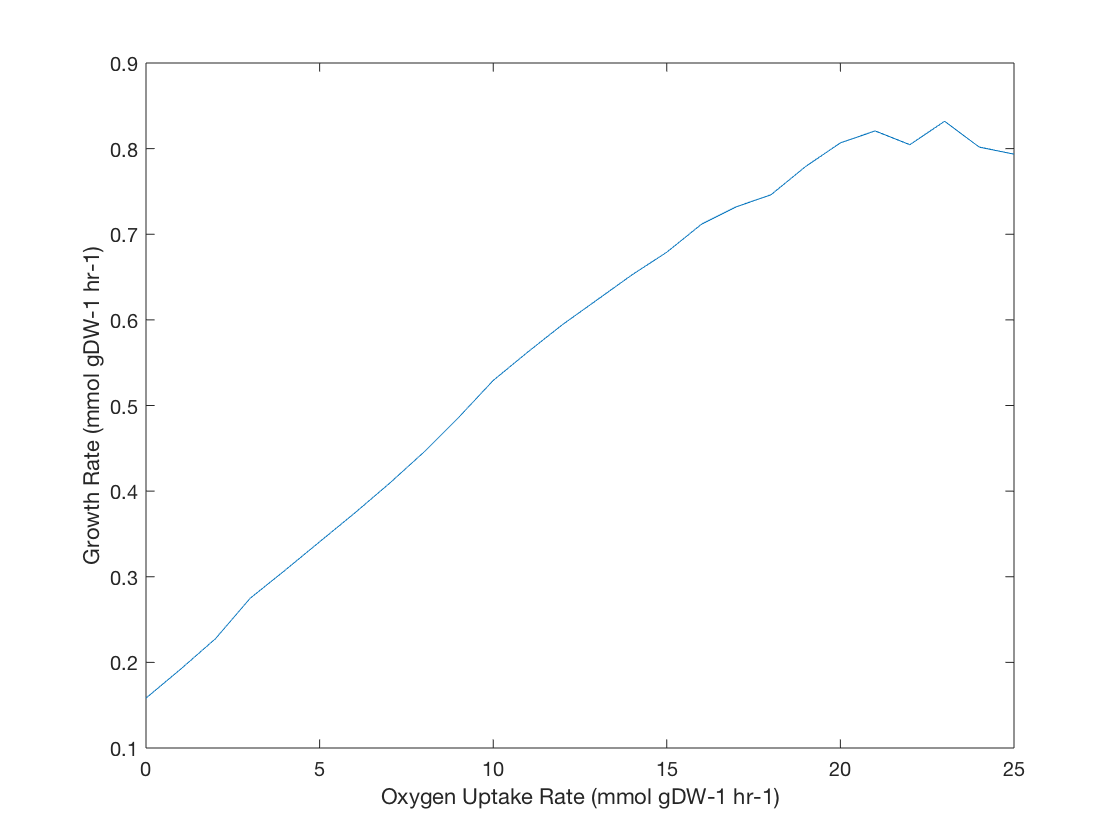

model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-10,'b');
oxygenUptakeRates = zeros(25,1);
growthRates = zeros(25,1);
for i = 0:25
	model = changeRxnBounds(model,'EX_o2(e)',-i,'b');
        oxygenUptakeRates(i+1)=-i;
	FBAsolution = optimizeCbModel(model,'max');
	growthRates(i+1) = FBAsolution.f;
end
figure; 
plot(-oxygenUptakeRates,growthRates,'-')
xlabel('Oxygen Uptake Rate (mmol gDW-1 hr-1)')
ylabel('Growth Rate (mmol gDW-1 hr-1)')

Figure 6  Robustness analysis for maximum growth rate while varying oxygen uptake rate with glucose uptake fixed at 10 mmol gDW-1 hr-1.

## Example 5.  Phenotypic phase plane analysis

When performing robustness analysis, one parameter is varied and the network state is calculated.  It is also possible to vary two parameters simultaneously and plot the results as a phenotypic phase plane [15].  These plots can reveal the interactions between two reactions in interesting ways.  

#### Calculate the phenotypic phase plane for maximum growth while varying glucose and oxygen uptake rates? What is the biochemical interpretation of each of the phase planes?

#### Hint: vary uptake rates between 0 and -20 mmol gDW-1 hr-1

The phenotypic phase plane for maximum growth while varying glucose and oxygen uptake rates will be calculated.  Although more sophisticated methods for computing phenotypic phase planes exist [16], they can be easily computed in a manner similar to the calculations for robustness analysis.  Instead of using one for loop to vary one reaction, two nested for loops are used to vary two reactions.  In this case, use for loops to vary the bounds of the glucose exchange reaction (EX_glc(e)) and oxygen exchange reaction (EX_o2(e)) between 0 and -20 mmol gDW-1 hr-1.  Use optimizeCbModel to perform FBA at each combination of glucose and oxygen uptake rates:

model = modelOri;
growthRates = zeros(21);
for i = 0:20
	for j = 0:20
		model = changeRxnBounds(model,'EX_glc(e)',-i,'b');
		model = changeRxnBounds(model,'EX_o2(e)',-j,'b');
		FBAsolution = optimizeCbModel(model,'max');
		growthRates(j+1,i+1) = FBAsolution.f;
	end
end

The resulting growth rates can be plotted as a 2-D graph (Figure 7a) or as a 3-D surface (Figure 7b). 

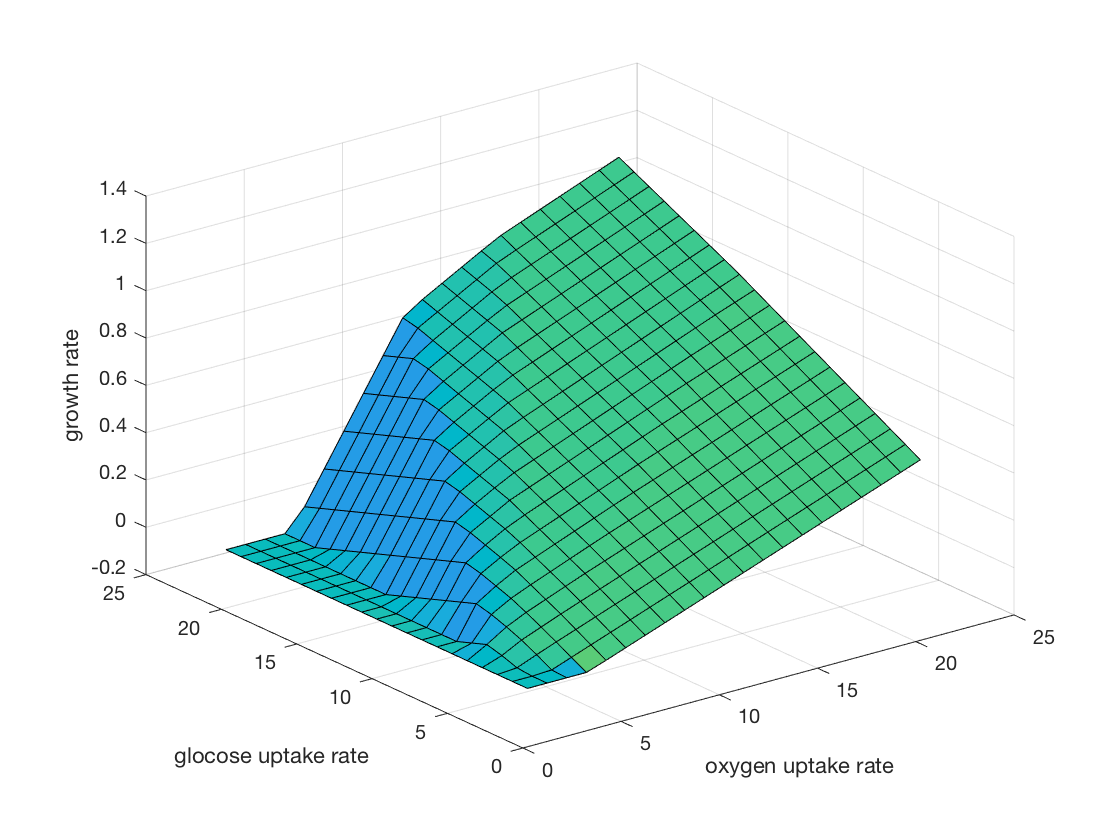

s=surfl(growthRates);
xlabel('oxygen uptake rate')
ylabel('glocose uptake rate')
zlabel('growth rate')

Figure 7a  Phenotypic phase planes for growth with varying glucose and oxygen uptake rates.  In phase 1, no growth is possible.  In phase 2, growth is limited by excess oxygen.  In phase 3, acetate is secreted; in phase 4, acetate and formate are secreted; and in phase 5, acetate, formate, and ethanol are secreted.  

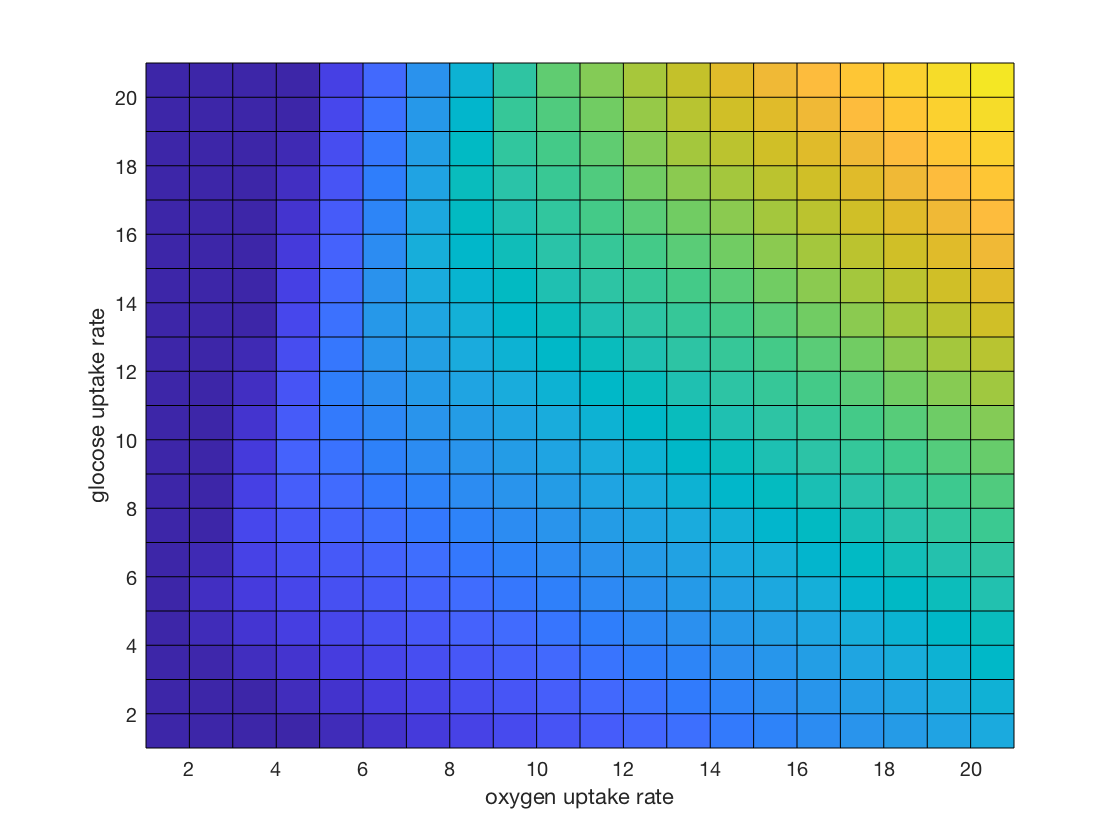

pcolor(growthRates)
xlabel('oxygen uptake rate')
ylabel('glocose uptake rate')

**Figure 7b**  Phenotypic phase planes for growth with varying glucose and oxygen uptake rates.  In phase 1, no growth is possible.  In phase 2, growth is limited by excess oxygen.  In phase 3, acetate is secreted; in phase 4, acetate and formate are secreted; and in phase 5, acetate, formate, and ethanol are secreted.  

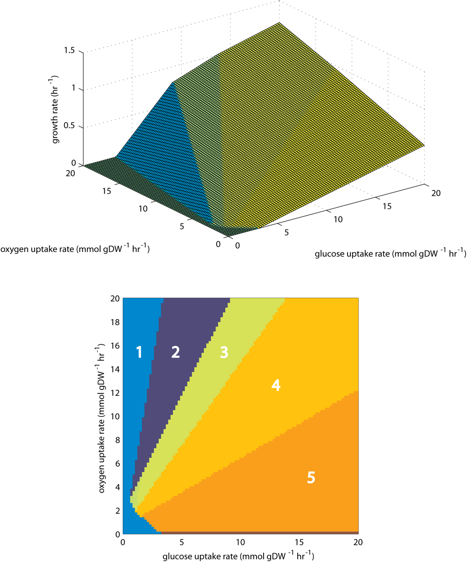

**Original Figure 7** Phenotypic phase planes for growth with varying glucose and oxygen uptake rates.  In phase 1, no growth is possible.  In phase 2, growth is limited by excess oxygen.  In phase 3, acetate is secreted; in phase 4, acetate and formate are secreted; and in phase 5, acetate, formate, and ethanol are secreted. 

It is clear from these plots that this surface has 5 distinct regions, and each one is a flat plane.  This is a general feature of phenotypic phase planes.  They do not form curved surfaces or other shapes.  Each of these phases has a qualitatively distinct phenotype, and all of the shadow prices (FBAsolution.y) are constant within each phase.  Phase 1 (on the far left of the plots) is characterized by 0 growth.  There is not enough glucose to meet the ATP maintenance requirement imposed by the ATPM reaction.  In phase 2, growth is limited by oxygen.  o2[e] has a shadow price of -0.0229 because there is not enough glucose to reduce all of the oxygen and produce biomass optimally.  The line between phase 2 and phase 3 is where glucose and oxygen are perfectly balanced and growth yield is highest.  In phases 3, 4, and 5, oxygen and glucose are both limiting growth.  There is not enough oxygen to fully oxidize glucose, so various compounds are produced by fermentation.

## Example 6.  Simulating gene knockouts

Just as growth in different environments can be simulated with FBA, gene knockouts can also be simulated by changing reaction bounds. To simulate the knockout of any gene, its associated reaction or reactions can simply be constrained to not carry flux.  By setting both the upper and lower bounds of a reaction to 0 mmol gDW-1 hr-1, a reaction is essentially knocked out, and is restricted from carrying flux.  The E. coli core model, like many other constraint-based models, contains a list of gene-protein-reaction interactions (GPRs), a list of Boolean rules that dictate which genes are connected with each reaction in the model.  When a reaction is catalyzed by isozymes (two different enzymes that catalyze the same reaction), the associated GPR contains an “or” rule, where either of two or more genes may be knocked out but the reaction will not be constrained. 

#### Which genes are required to be knocked out to eliminate flux through the phosphofructokinase (PFK) reaction?

#### Hint: study the model

The GPR for phosphofructokinase (PFK) is “b1723 (pfkB) or b3916 (pfkA),” so according to this Boolean rule, both pfkB and pfkA must be knocked out to restrict this reaction.  When a reaction is catalyzed by a protein with multiple essential subunits, the GPR contains an “and” rule, and if any of the genes are knocked out the reaction will be constrained to 0 flux.  Succinyl-CoA synthetase (SUCOAS), for example, has the GPR “b0728 (sucC) and b0729 (sucD),” so knocking out either of these genes will restrict this reaction.  Some reactions are catalyzed by a single gene product, while others may be associated with ten or more genes in complex associations.

#### What is the growth rate of E. coli when the gene b1852 (zwf) is knocked out?

#### Hint: `deleteModelGenes`

The COBRA Toolbox contains a function called `deleteModelGenes` that uses the GPRs to constrain the correct reactions.  Then FBA may be used to predict the model phenotype with gene knockouts.  For example, growth can be predicted for E. coli growing aerobically on glucose with the gene b1852 (zwf), corresponding to the reaction glucose-6-phospahte dehydrogenase (G6PDH2r), knocked out.  The FBA predicted growth rate of this strain is 1.6329 hr-1, which is slightly lower than the growth rate of 1.6531 hr-1 for wild-type E. coli because the cell can no longer use the oxidative branch of the pentose phosphate pathway to generate NADPH.  Using FBA to predict the phenotypes of gene knockouts is especially useful in predicting essential genes.  When the gene b2779 (eno), corresponding to the enolase reaction (ENO), is knocked out, the resulting growth rate on glucose is 0 hr-1.  Growth is no longer possible because there is no way to convert glucose into TCA cycle intermediates without this glycolysis reaction, so this gene is predicted to be essential.  Because FBA can compute phenotypes very quickly, it is feasible to use it for large scale computational screens for gene essentiality, including screens for two or more simultaneous knockouts.  

#### Knockout every pairwise combination of the 136 genes in the E. coli core model and display the results.

#### Hint: `doubleGeneDeletion`

Figure 8 shows the results of a double knockout screen, in which every pairwise combination of the 136 genes in the E. coli core model were knocked out.  The code to produce this figure is:

model = modelOri;
[grRatio,grRateKO,grRateWT] = doubleGeneDeletion(model);

Single deletion analysis to remove lethal genes
100%    [........................................]
131 non-lethal genes
Double gene deletion analysis
Total of 8515 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time


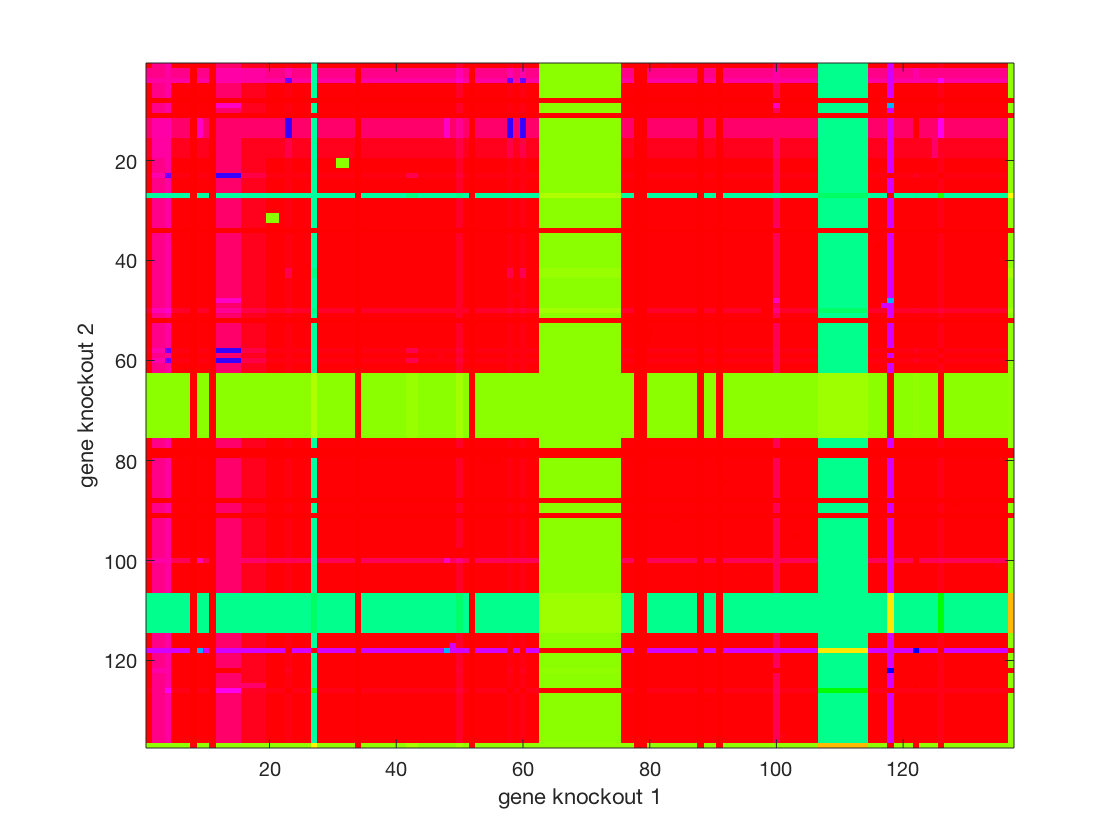

figure;
imagesc(grRatio);
colormap('hsv')
xlabel('gene knockout 1')
ylabel('gene knockout 2')

**Figure 8  **Gene knockout screen on glucose under aerobic conditions.  Each of the 136 genes in the core E. coli model were knocked out in pairs, and the resulting relative growth rates were plotted.  In this figure, genes are ordered by their b number.  Some genes are always essential, and result in a growth rate of 0 when knocked out no matter which other gene is also knocked out.  Other genes form synthetic lethal pairs, where knocking out only one of the genes has no effect on growth rate, but knocking both out is lethal.  Growth rates in this figure are relative to wild-type.

## Example 7.  Which genes are essential for which biomass precursor? 

Earlier, we saw how to determine essential genes for growth. Here we will repeat the same analysis but instead of optimizing for the biomass production, we will optimize for the synthesis of all biomass precursors individually. 

#### Which genes are essential for synthesis of each biomass precursor?

#### Hint: `addDemandReaction`

Therefore, we have to add a demand reaction for each biomass precursor to the model and perform a gene deletion study for each demand reaction.  First, the components of the biomass reaction can be identified and demand reactions can be added by using the addDemandReaction function:

model = modelOri;
bool=model.S(:,strcmp(model.rxns,'Biomass_Ecoli_core_N(w/GAM)-Nmet2'))~=0;
biomassComponents=model.mets(bool);
[modelBiomass,rxnNames] = addDemandReaction(model,biomassComponents);

Adding the following reactions to the model:
DM_3pg[c]	3pg[c] 	->	
DM_accoa[c]	accoa[c] 	->	
DM_adp[c]	adp[c] 	->	
DM_akg[c]	akg[c] 	->	
DM_atp[c]	atp[c] 	->	
DM_coa[c]	coa[c] 	->	
DM_e4p[c]	e4p[c] 	->	
DM_f6p[c]	f6p[c] 	->	
DM_g3p[c]	g3p[c] 	->	
DM_g6p[c]	g6p[c] 	->	
DM_gln-L[c]	gln-L[c] 	->	
DM_glu-L[c]	glu-L[c] 	->	
DM_h2o[c]	h2o[c] 	->	
DM_h[c]	h[c] 	->	
DM_nad[c]	nad[c] 	->	
DM_nadh[c]	nadh[c] 	->	
DM_nadp[c]	nadp[c] 	->	
DM_nadph[c]	nadph[c] 	->	
DM_oaa[c]	oaa[c] 	->	
DM_pep[c]	pep[c] 	->	
DM_pi[c]	pi[c] 	->	
DM_pyr[c]	pyr[c] 	->	
DM_r5p[c]	r5p[c] 	->	


Next, gene knockout screens can be performed with each of these demand reactions set as the objective, one at a time:


for i = 1:length(rxnNames)
    modelBiomass = changeObjective(modelBiomass,rxnNames{i});
    [grRatio,grRateKO,grRateWT,hasEffect,delRxns,fluxSolution] = singleGeneDeletion(modelBiomass,'FBA',model.genes,0);
    biomassPrecursorGeneEss(:,i) = grRateKO;
    biomassPrecursorGeneEssRatio(:,i) = grRatio;
end

1111111111111111111111100%    [........................................]


%biomassPrecursorGeneEssRatio(~isfinite(biomassPrecursorGeneEssRatio))=0;

The resulting matrix biomassPrecursorGeneEssRatio is plotted with the imagesc function in Figure 9, and indicate which biomass precursors become blocked by certain gene knockouts.  

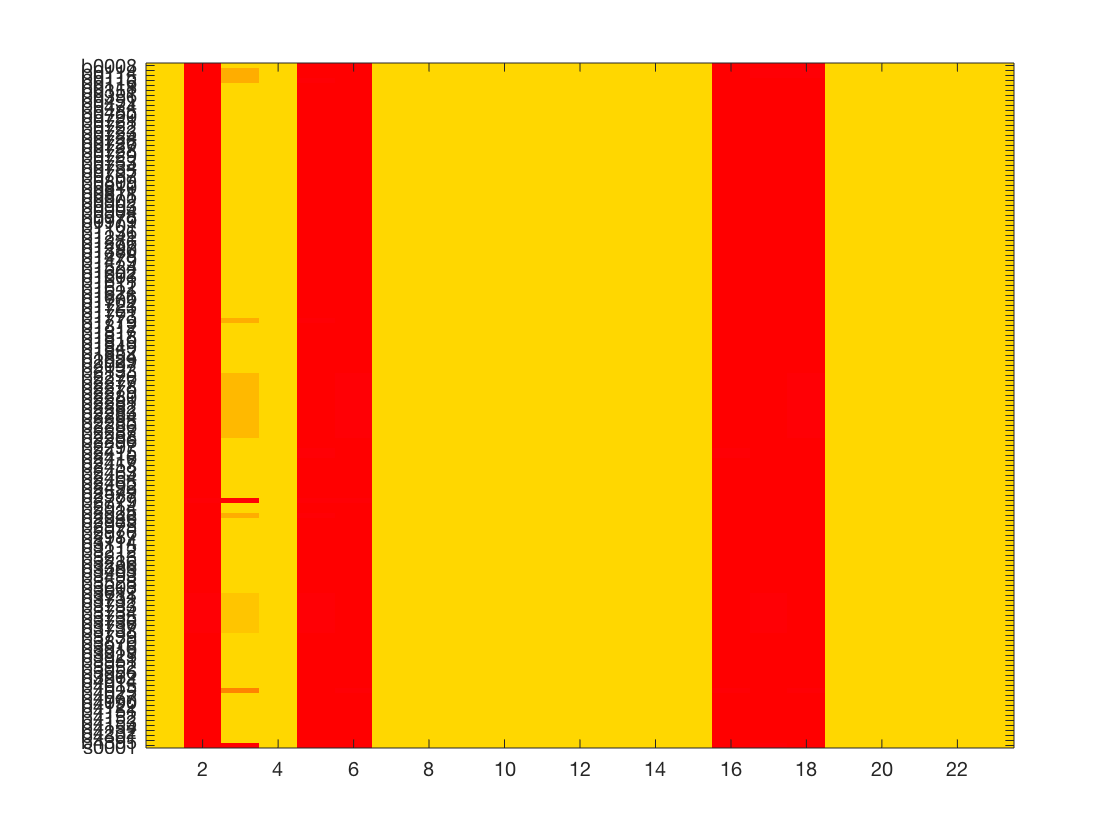

figure;
imagesc(biomassPrecursorGeneEssRatio);
colormap('hsv')
yticks(1:length(model.genes));
yticklabels(model.genes)

Figure 9  Gene essentiality for biomass precursor synthesis. Heat map shows the relative biomass precursor synthesis rate of mutant compared to wild-type.   The 23 biomass precursors are 3pg, accoa, adp, akg, atp, coa, e4p, f6p, g3p, g6p, gln-L, glu-L, h2o, h, nad, nadh, nadp, nadph, oaa, pep, pi, pyr, r5p.

#### Which biomass precursors cannot be net synthesised by the E. coli core model? What does this say about the E. coli core model itself?

#### Hint: think about steady state versus mass balance

Some precursors (like atp[c]) cannot be net produced by any of the gene knockout strains because of the demand reactions that consume them and there are no set of reactions that de novo synthesise that precursor.  The addDemandReacton function produces a demand reaction that does not regenerate ADP when ATP is consumed or NAD+ when NADH is consumed, so these reactions cannot carry flux at steady-state. The genome-scale E. coli model contains all the reactions for de novo synthesis of ATP.

## Example 8.  Which non-essential gene knockouts have the greatest effect on the network flexibility?

Another question one might be interested in asking is what are the consequences for the network of deleting a non-essential gene? Given an objective, the flux span is the difference between the maximium and minimum alternate optimal flux values for a reaction. A reaction is said to become more flexible if its flux span increases and less flexible if its flux span decreases.

#### What reactions are increased and decreased in flux span in response to deletion of these 6 genes?  `{'b0114', 'b0723', 'b0726', 'b0767', 'b1602', 'b1702'} With reference to a particular example, w`hat is the biochemical interpretation of an increased flux span in response to a gene deletion? 

#### Hint: `fluxVariability`, `hist`

To address this question, first delete the network genes individually (a single gene deletion study) and then perform FVA (Example 3) on non-essential gene deletion strains. In many cases one would expect that the deletion of a gene has only minor consequences to the network, especially if the deletion does not alter the maximal growth rate. In some cases however, the deletion may reduce the overall network flexibility or maybe even increase the flux range through specific reactions. In fact, this latter property is used to design optimal production strains (e.g., using OptKnock [9]), by redirecting fluxes through the network. 

The absolute flux span is a measure of flux range for each reaction. It is calculated as fi = abs(vmax,i – vmin,i), where vmin,i and vmax,i are the minimal and maximal flux rate as determined using FVA.  First, calculate wild-type flux variability:

[minFluxAll(:,1),maxFluxAll(:,1)] = fluxVariability(model);

Next, calculate the knockout strain flux variablities and flux spans:

genes=model.genes([2,14,16,23,42,48]);
for i = 1 : length(genes)
    [modelDel] = deleteModelGenes(model,genes{i});
    [minFluxAll(:,i+1),maxFluxAll(:,i+1)] = fluxVariability(modelDel);
end

fluxSpan = abs(maxFluxAll - minFluxAll);
for i = 1 : size(fluxSpan,2)
    fluxSpanRelative(:,i) = fluxSpan(:,i)./fluxSpan(:,1);
end

This example with six mutant strains shows that the majority of the network reactions have reduced flux span compared to wild-type (Figure 10). However, some of these knockout strains have a few reactions which have much higher flux span than wildtype. For example, in one of the knockout strains (ΔsucA), the flux span is increased 14 times through the phosphoenolpyruvate carboxykinase reaction (PPCK).

Finally, histograms can be plotted to show how many reactions have increased or decreased flux spans for each knockout:

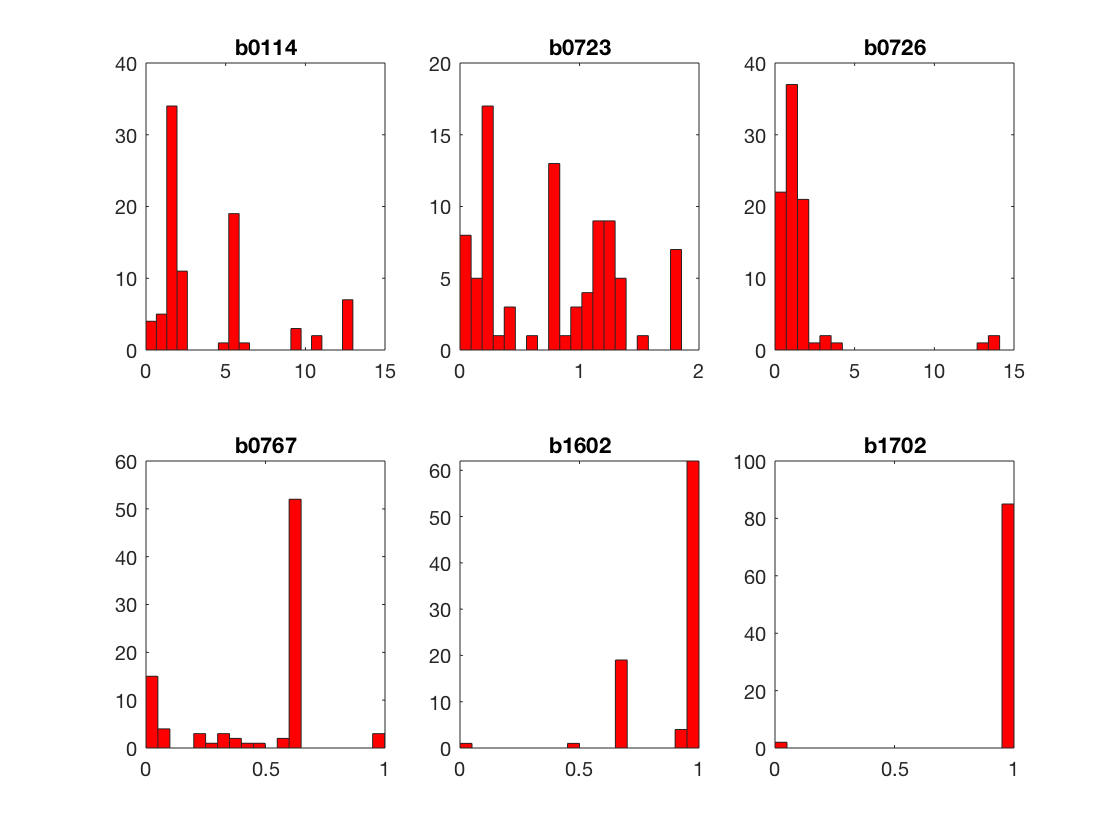

for i =2:7
    subplot(2,3,i-1)
    hist(fluxSpanRelative(:,i),20);
    title(genes{i-1});
end

Figure 10  Histograms of relative flux spans for 6 gene knockout mutants.

## TIMING

*2 hrs*

## *Acknowledgments*

This tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1.	Becker, S.A. et al. Quantitative prediction of cellular metabolism with constraint-based models: The COBRA Toolbox. Nat. Protocols 2, 727-738 (2007).

2.	Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

3.	Covert, M.W., Knight, E.M., Reed, J.L., Herrgard, M.J. & Palsson, B.O. Integrating high-throughput and computational data elucidates bacterial networks. Nature 429, 92-96 (2004).

4.	Segre, D., Vitkup, D. & Church, G.M. Analysis of optimality in natural and perturbed metabolic networks. Proceedings of the National Academy of Sciences of the United States of America 99, 15112-15117 (2002).

5.	Shlomi, T., Berkman, O. & Ruppin, E. Regulatory on/off minimization of metabolic flux changes after genetic perturbations. Proceedings of the National Academy of Sciences of the United States of America 102, 7695-7700 (2005).

6.	Reed, J.L., Famili, I., Thiele, I. & Palsson, B.O. Towards multidimensional genome annotation. Nat Rev Genet 7, 130-141 (2006).

7.	Satish Kumar, V., Dasika, M.S. & Maranas, C.D. Optimization based automated curation of metabolic reconstructions. BMC bioinformatics 8, 212 (2007).

8.	Kumar, V.S. & Maranas, C.D. GrowMatch: an automated method for reconciling in silico/in vivo growth predictions. PLoS Comput Biol 5, e1000308 (2009).

9.	Burgard, A.P., Pharkya, P. & Maranas, C.D. Optknock: a bilevel programming framework for identifying gene knockout strategies for microbial strain optimization. Biotechnology and bioengineering 84, 647-657 (2003).

10.	Patil, K.R., Rocha, I., Forster, J. & Nielsen, J. Evolutionary programming as a platform for in silico metabolic engineering. BMC bioinformatics 6, 308 (2005).

11.	Pharkya, P., Burgard, A.P. & Maranas, C.D. OptStrain: a computational framework for redesign of microbial production systems. Genome research 14, 2367-2376 (2004).

12.	Varma, A. & Palsson, B.O. Metabolic capabilities of Escherichia coli: I. Synthesis of biosynthetic precursors and cofactors. Journal of Theoretical Biology 165, 477-502 (1993).

13.	Mahadevan, R. & Schilling, C.H. The effects of alternate optimal solutions in constraint-based genome-scale metabolic models. Metabolic engineering 5, 264-276 (2003).

14.	Edwards, J.S. & Palsson, B.O. Robustness analysis of the Escherichia coli metabolic network. Biotechnology Progress 16, 927-939 (2000).

15.	Edwards, J.S., Ramakrishna, R. & Palsson, B.O. Characterizing the metabolic phenotype: a phenotype phase plane analysis. Biotechnology and bioengineering 77, 27-36. (2002).

16.	Bell, S.L. & Palsson, B.O. Phenotype phase plane analysis using interior point methods. Computers & Chemical Engineering 29, 481-486 (2005).

17.	Palsson, B.O. Systems biology: properties of reconstructed networks. (Cambridge University Press, New York; 2006).

18.	Barabasi, A.L. & Oltvai, Z.N. Network biology: understanding the cell's functional organization. Nat Rev Genet 5, 101-113 (2004).

19.	Mahadevan, R. & Palsson, B.O. Properties of metabolic networks: structure versus function. Biophysical journal 88, L07-09 (2005).

20.	Price, N.D., Schellenberger, J. & Palsson, B.O. Uniform Sampling of Steady State Flux Spaces: Means to Design Experiments and to Interpret Enzymopathies. Biophysical journal 87, 2172-2186 (2004).

21.	Thiele, I., Price, N.D., Vo, T.D. & Palsson, B.O. Candidate metabolic network states in human mitochondria: Impact of diabetes, ischemia, and diet. The Journal of biological chemistry 280, 11683-11695 (2005).

22. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).